y_cycleLife = [battery_dataset_v1(idx).cycle_life ]';
x_chargeCurrent = (reshape([battery_dataset_v1(idx).Ic],100,length(y_cycleLife)))';
[y_cycleLife_norm_all,y_cycleLife_max,y_cycleLife_min,y_cycleLife_rate,x_chargeCurrent_norm_all,x_chargeCurrent_max,x_chargeCurrent_min,x_chargeCurrent_rate] = minmax_norm_all(y_cycleLife,x_chargeCurrent);


% train  70 
% val    15
% test   15


chargeCurrentIndex = [1:100]

chargeCurrentIndex =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


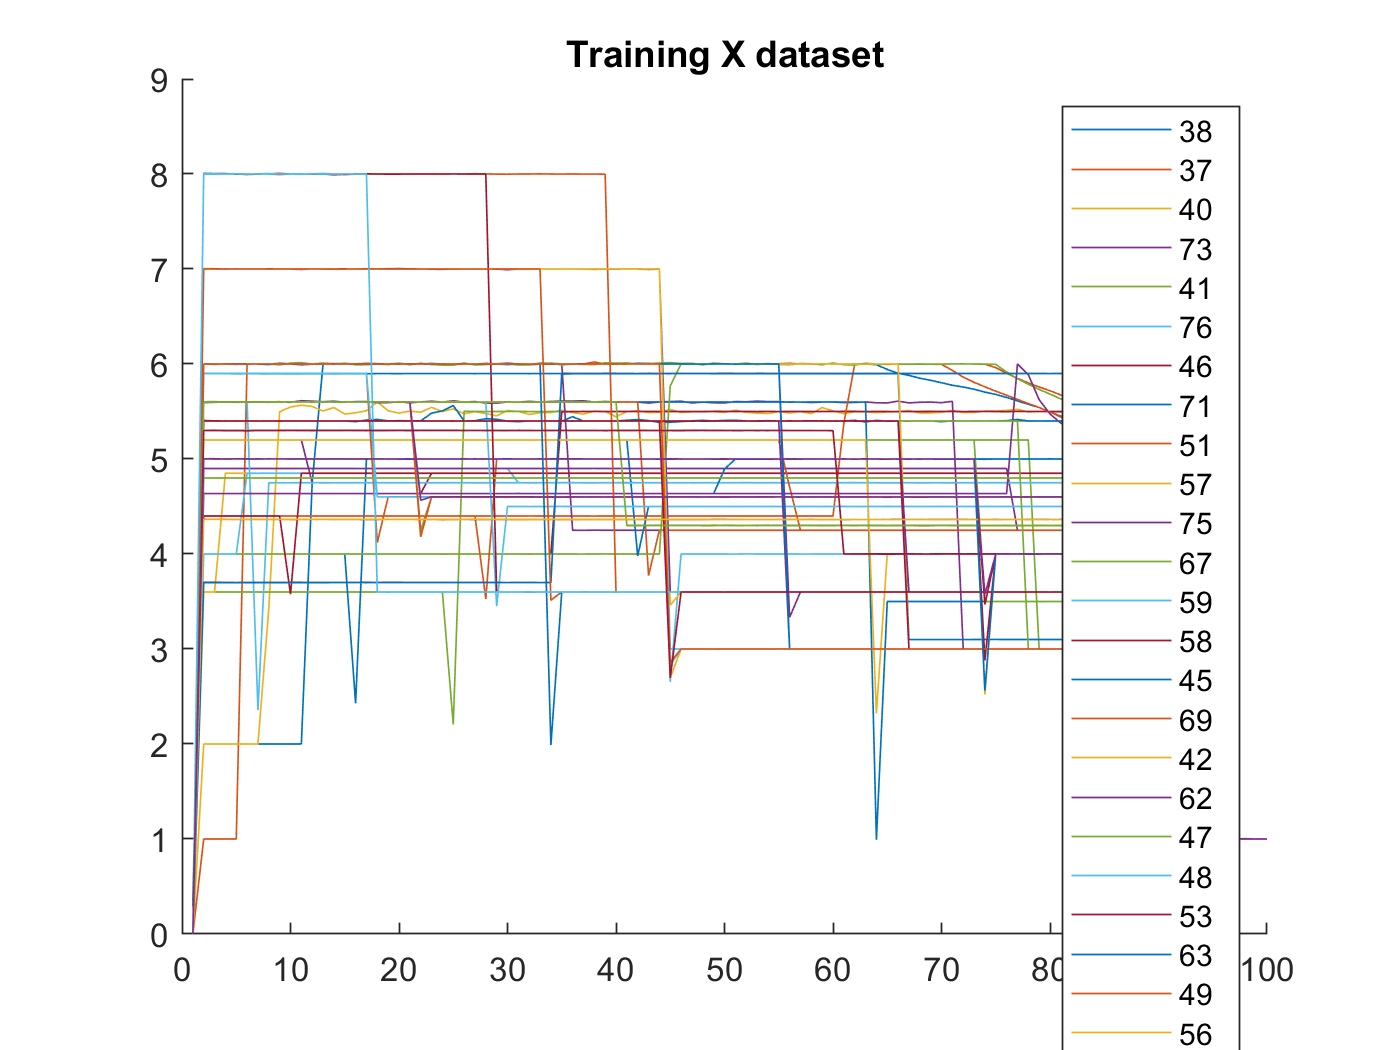

% https://blogs.mathworks.com/pick/2011/02/11/create-multi-column-plot-legends/?from=kr

nLines = length(idxTrain);
legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxTrain)
    i = idxTrain(j);
    plot(chargeCurrentIndex,battery_dataset_v1(i).Ic)
    legend_str{j} = num2str(i);
end
hold off
title 'Training X dataset'
legend(legend_str)%,'location','NorthWest')

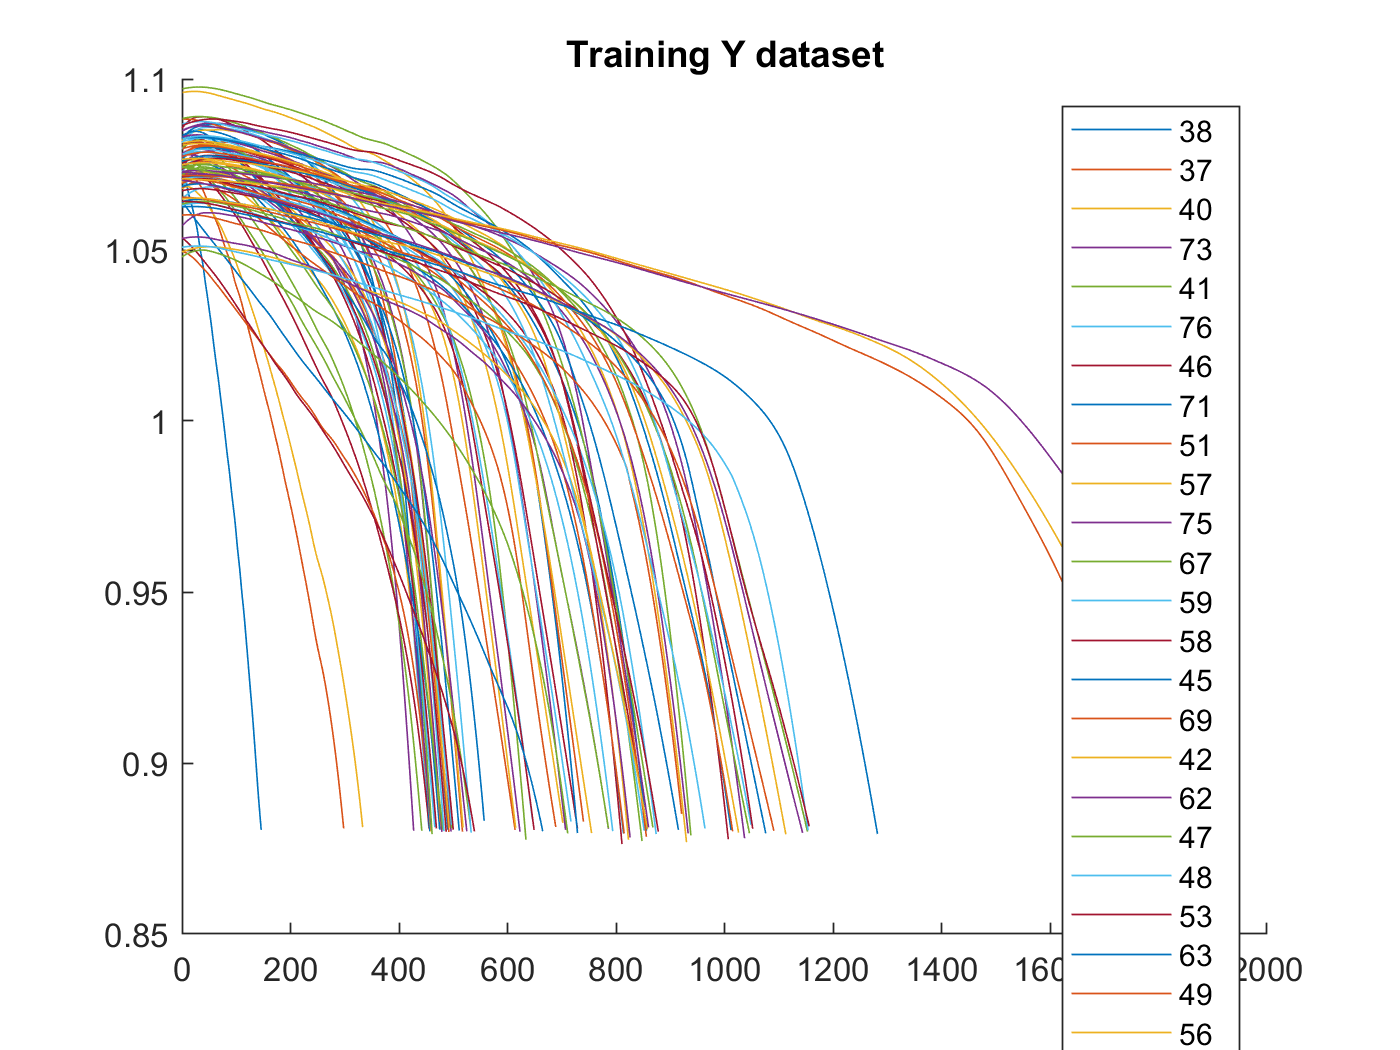


legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxTrain)
    i = idxTrain(j);
    plot(battery_dataset_v1(i).cycle,battery_dataset_v1(i).QDischargeSmooth)
    legend_str{j} = num2str(i);
end
hold off
title 'Training Y dataset'
legend(legend_str) %,'location','NorthWest')

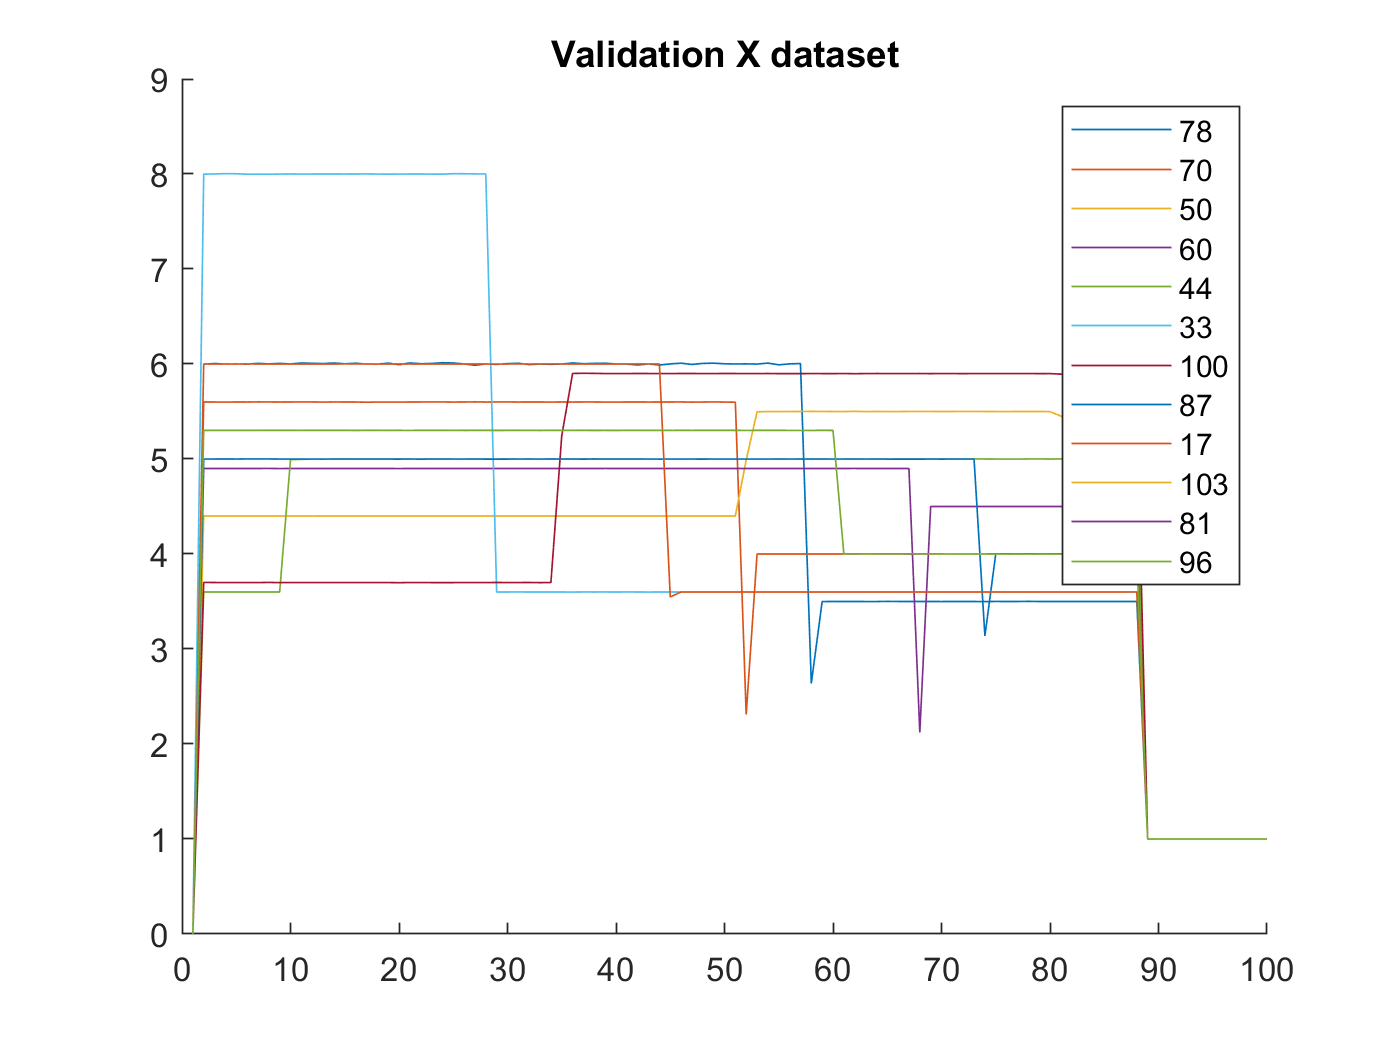



nLines = length(idxValid);
legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxValid)
    i = idxValid(j);
    plot(chargeCurrentIndex,battery_dataset_v1(i).Ic)
    legend_str{j} = num2str(i);
end
hold off
title 'Validation X dataset'
legend(legend_str)

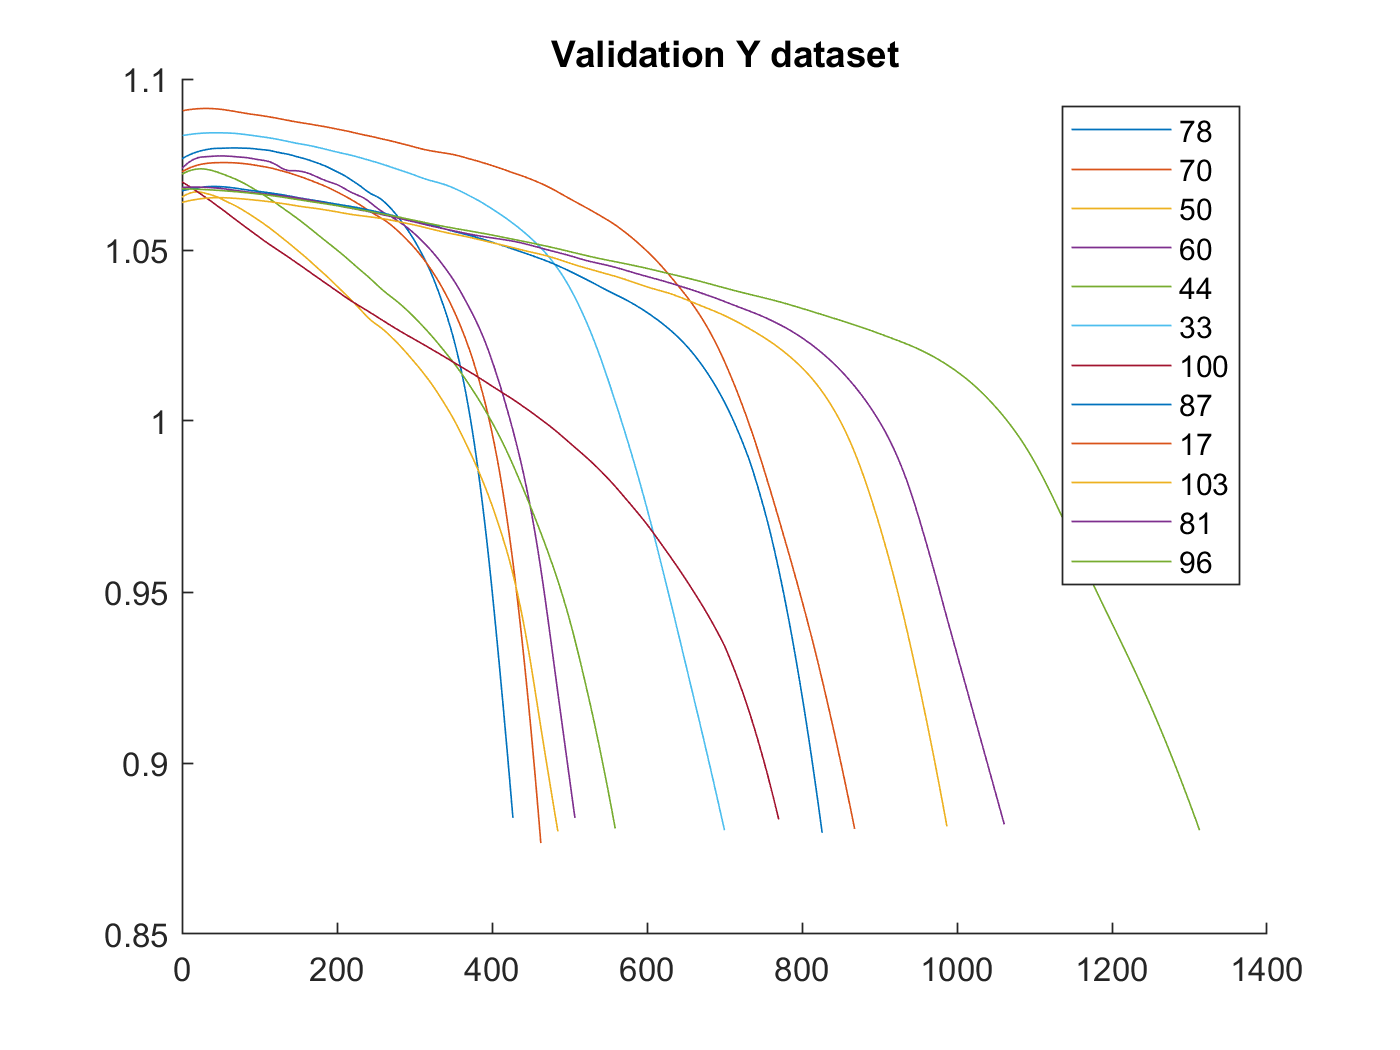


legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxValid)
    i = idxValid(j);
    plot(battery_dataset_v1(i).cycle,battery_dataset_v1(i).QDischargeSmooth)
    legend_str{j} = num2str(i);
end
hold off
title 'Validation Y dataset'
legend(legend_str)

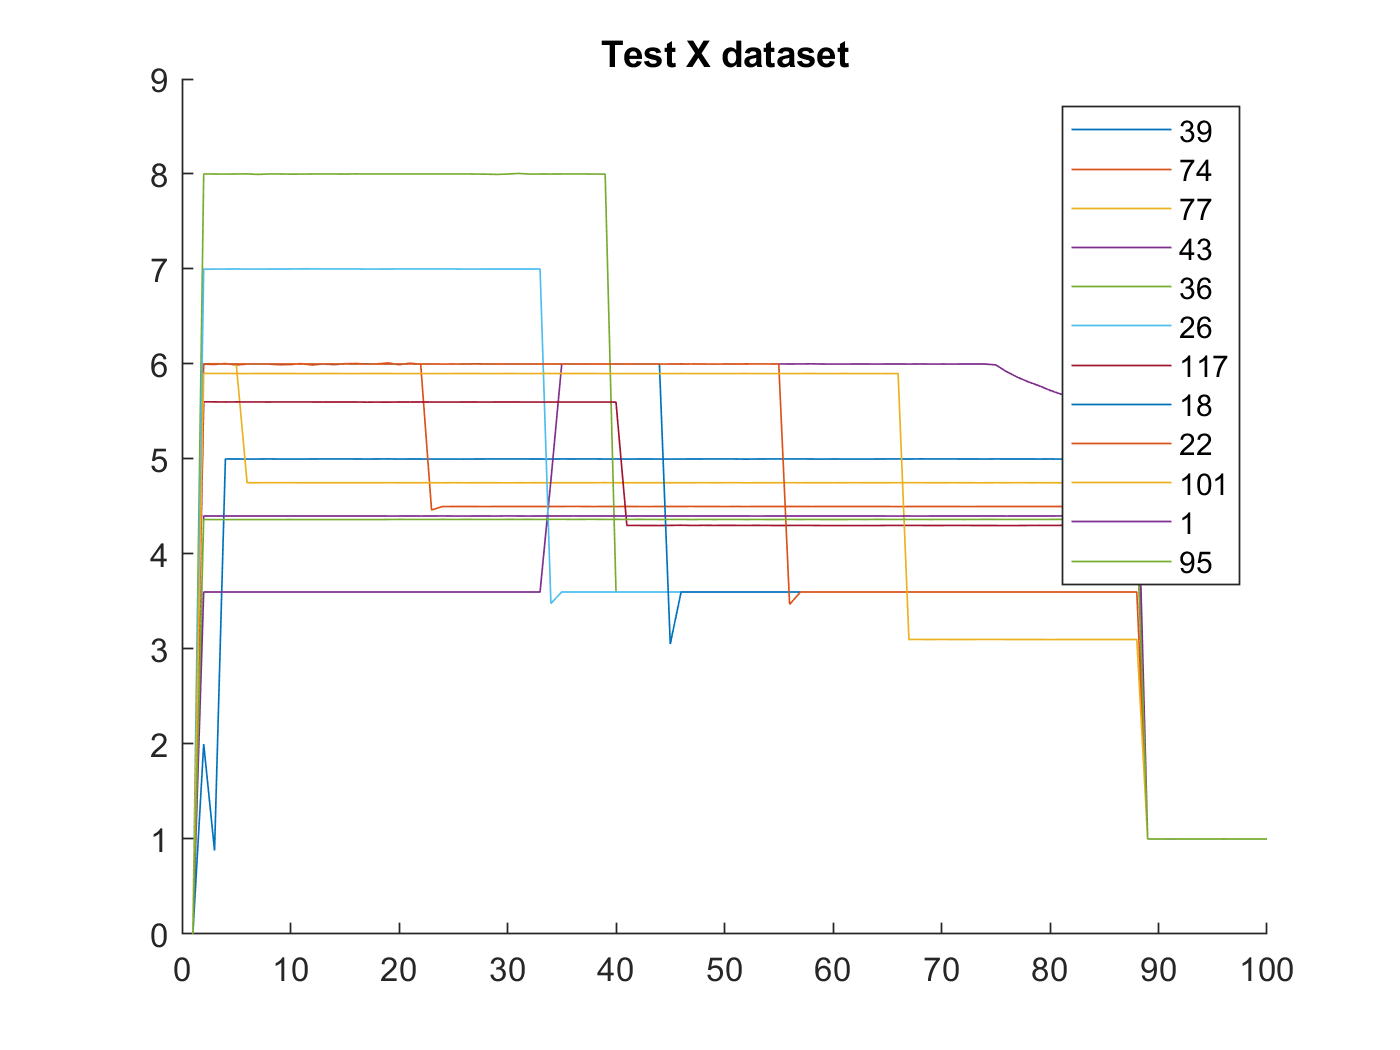


nLines = length(idxTest);
legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxTest)
    i = idxTest(j);
    plot(chargeCurrentIndex,battery_dataset_v1(i).Ic)
    legend_str{j} = num2str(i);
end
hold off
title 'Test X dataset'
legend(legend_str)

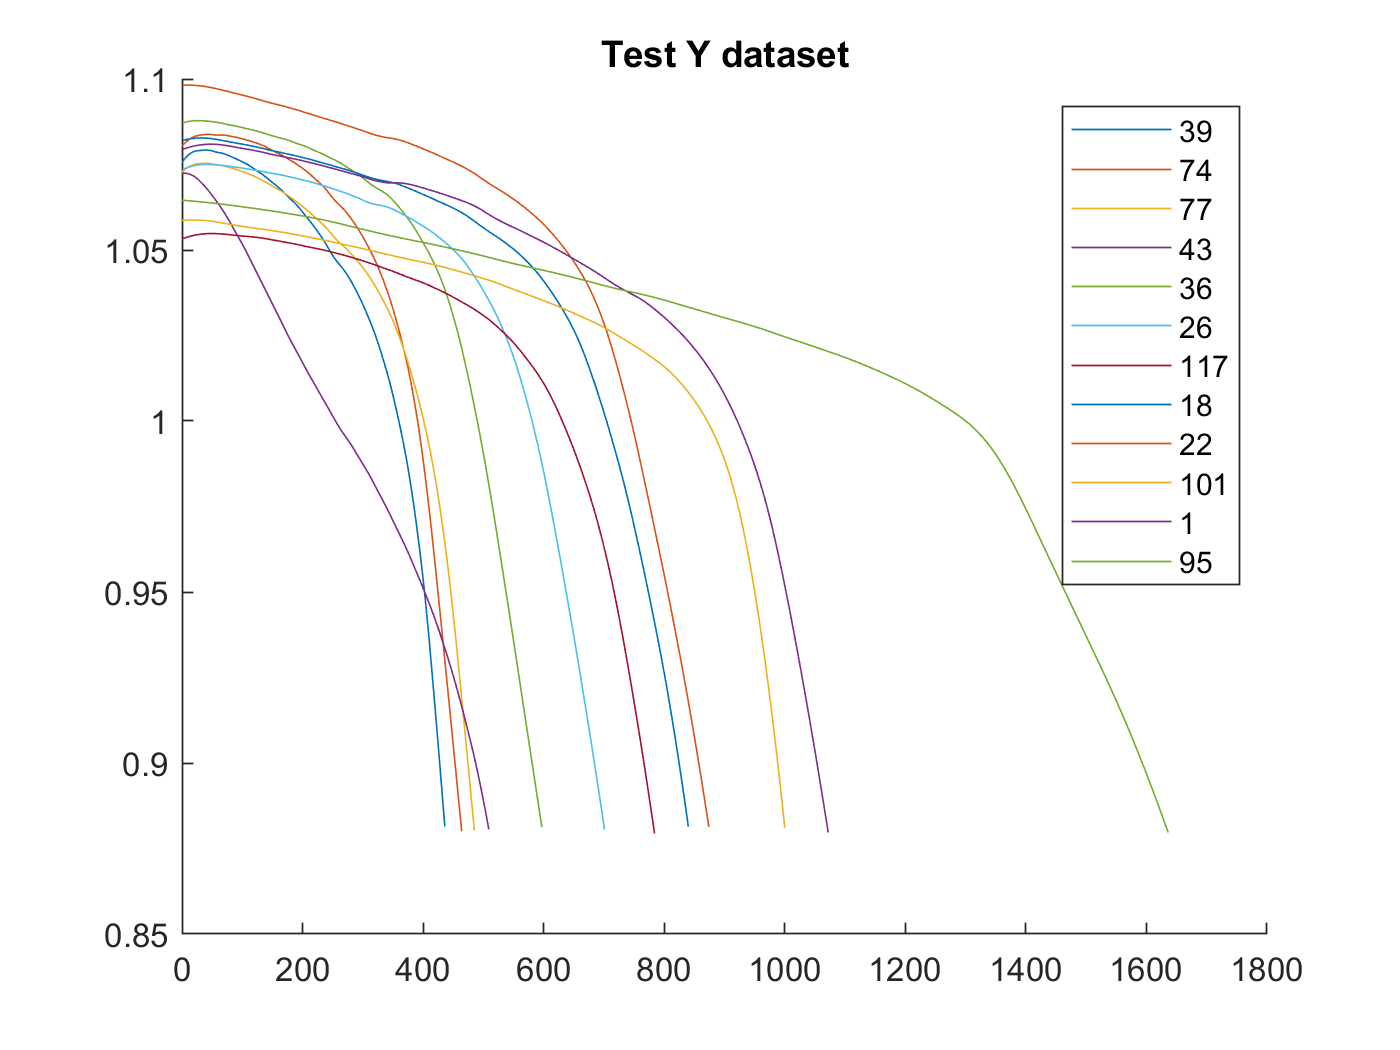


figure
hold on 
for j = 1 : length(idxTest)
    i = idxTest(j);
    plot(battery_dataset_v1(i).cycle,battery_dataset_v1(i).QDischargeSmooth)
    legend_str{j} = num2str(i);
end
hold off
title 'Test Y dataset'
legend(legend_str)

idx = idxAll;
y_cycleLife = [battery_dataset_v1(idx).cycle_life ]';
x_chargeCurrent = (reshape([battery_dataset_v1(idx).Ic],100,length(y_cycleLife)))';
[y_cycleLife_norm_all,y_cycleLife_max,y_cycleLife_min,y_cycleLife_rate,x_chargeCurrent_norm_all,x_chargeCurrent_max,x_chargeCurrent_min,x_chargeCurrent_rate] = minmax_norm_all(y_cycleLife,x_chargeCurrent);

idx = idxTrain;
y_cycleLife_valid = [battery_dataset_v1(idx).cycle_life ]';
x_chargeI_train = (reshape([battery_dataset_v1(idx).Ic],100,length(y_cycleLife_valid)))';

idx = idxValid;
y_cycleLife_valid = [battery_dataset_v1(idx).cycle_life ]';
x_chargeI_valid = (reshape([battery_dataset_v1(idx).Ic],100,length(y_cycleLife_valid)))';

idx = [idxTrain idxValid];
cycleLife_train_valid = [battery_dataset_v1(idx).cycle_life ]';
x_chargeI_train_valid = (reshape([battery_dataset_v1(idx).Ic],100,length(cycleLife_train_valid)))';

idx = idxTest;
cycleLife_test = [battery_dataset_v1(idx).cycle_life ]';
x_chargeI_test = (reshape([battery_dataset_v1(idx).Ic],100,length(cycleLife_test)))';


input_size = 100;
ryan3_gen_dat_desc = 'ryan3_gen_dat';
save('ryan3_gen_data.mat','ryan3_gen_dat_desc');
save('ryan3_gen_data.mat','battery_dataset_v1' ,'-append')


save('ryan3_gen_data.mat','y_cycleLife_norm_all' ,'-append')
save('ryan3_gen_data.mat','y_cycleLife_max' ,'-append')
save('ryan3_gen_data.mat','y_cycleLife_min' ,'-append')
save('ryan3_gen_data.mat','y_cycleLife_rate' ,'-append')
save('ryan3_gen_data.mat','x_chargeCurrent_norm_all' ,'-append')
save('ryan3_gen_data.mat','x_chargeCurrent_max' ,'-append')
save('ryan3_gen_data.mat','x_chargeCurrent_min' ,'-append')
save('ryan3_gen_data.mat','x_chargeCurrent_rate' ,'-append')

save('ryan3_gen_data.mat', 'y_cycleLife_valid'             ,'-append')
save('ryan3_gen_data.mat', 'y_cycleLife_valid'             ,'-append') 
save('ryan3_gen_data.mat', 'cycleLife_train_valid'       ,'-append')
save('ryan3_gen_data.mat', 'cycleLife_test'              ,'-append')
save('ryan3_gen_data.mat', 'x_chargeI_train'         ,'-append')
save('ryan3_gen_data.mat', 'x_chargeI_valid'         ,'-append')
save('ryan3_gen_data.mat', 'x_chargeI_train_valid'   ,'-append')
save('ryan3_gen_data.mat', 'x_chargeI_test'          ,'-append')           

result = zeros();
result = [0 0];

idx = idxAll

idx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


i=1 

i = 1

j = idx(i)

j = 1

battery_dataset_v1(i).QDischargeSmooth(1) 

ans = 1.0795



battery_dataset = zeros()

v1_battery_dataset = 0

battery_dataset = battery_dataset_v1(1)

v1_battery_dataset = struct with fields:
               policy: '4_4C-80PER_4_4C'
      policy_readable: '4.4C(80%)-4.4C'
           channel_id: "7"
           cycle_life: 1072
                  key: "b1c6"
             batchNum: 1
               batNum: 6
           chargetime: [1072×1 double]
                cycle: [1072×1 double]
                   IR: [1072×1 double]
              QCharge: [1072×1 double]
           QDischarge: [1072×1 double]
                 Tavg: [1072×1 double]
                 Tmin: [1072×1 double]
                 Tmax: [1072×1 double]
                Vdlin: [1000×1 double]
                   Vc: [1072×100 double]
                   Tc: [1072×100 double]
                   Vd: [1072×100 double]
                   Td: [1072×100 double]
              VT_leng: 100
                   Ic: [1×100 double]
                   Id: [1×100 double]
     QDischargeSmooth: [1072×1 double]
    QDischargePolyMdl: [-9.6874e-13 1.6385e-09 -9.4860e-07 1.5422e-04 1.0742]
    QDis

i=1;
for ii = 1:1000
    if battery_dataset_v1(i).QDischargeSmooth(ii) <= 1.048
        % skip count 
        break
    end
end
ii

ii = 644

battery_dataset(i) = battery_dataset_v1(i);
battery_dataset(i).cycle_life = battery_dataset_v1(i).cycle_life - ii;
battery_dataset_v1(i).cycle_life

ans = 1072

battery_dataset(i).cycle_life

ans = 428

battery_dataset(i).chargetime([1:ii],:) = [] ;

size(battery_dataset_v1(i).chargetime)

ans =         1072           1


size(battery_dataset(i).chargetime)

ans =    428     1


battery_dataset(i).cycle = [] ;
battery_dataset(i).cycle = battery_dataset_v1(i).cycle(1:end-ii,:);
battery_dataset(i).IR([1:ii],:) = [] ;
battery_dataset(i).QCharge([1:ii],:) = [] ;
battery_dataset(i).QDischarge([1:ii],:) = [] ;
battery_dataset(i).Tavg([1:ii],:) = [] ;
battery_dataset(i).Tmin([1:ii],:) = [] ;
battery_dataset(i).Tmax([1:ii],:) = [] ;
battery_dataset(i).Vc([1:ii],:) = [] ;
battery_dataset(i).Vd([1:ii],:) = [] ;
battery_dataset(i).Tc([1:ii],:) = [] ;
battery_dataset(i).Td([1:ii],:) = [] ;
battery_dataset(i).QDischargeSmooth([1:ii],:) = [] ;
battery_dataset(i).QDischargePolyMdl = [];
battery_dataset(i).QDischargePolyMdl = polyfit(battery_dataset(i).cycle, battery_dataset(i).QDischargeSmooth,4);
battery_dataset(i).QDischargePolyfit = [];
battery_dataset(i).QDischargePolyfit = polyval(battery_dataset.QDischargePolyMdl,battery_dataset.cycle')';


% get first capacity
for i = 1:length(idx)
    %j = idx(i);
    initC = battery_dataset_v1(i).QDischargeSmooth(1) ;
    result(i,:) = [ i initC ];
    for ii = 1:battery_dataset_v1(i).cycle_life
        if battery_dataset_v1(i).QDischargeSmooth(ii) <= 1.048
            % skip count 
            break
        end
        if ii == battery_dataset_v1(i).cycle_life
            error_is = true;
        end
    end
    battery_dataset(i) = battery_dataset_v1(i);
    battery_dataset(i).cycle_life = battery_dataset_v1(i).cycle_life - ii;
    %battery_dataset_v1(i).cycle_life
    %battery_dataset(i).cycle_life
    battery_dataset(i).chargetime([1:ii],:) = [] ;
    
    %size(battery_dataset_v1(i).chargetime)
    %size(battery_dataset(i).chargetime)
    battery_dataset(i).cycle = [] ;
    battery_dataset(i).cycle = battery_dataset_v1(i).cycle(1:end-ii,:);
    battery_dataset(i).IR([1:ii],:) = [] ;
    battery_dataset(i).QCharge([1:ii],:) = [] ;
    battery_dataset(i).QDischarge([1:ii],:) = [] ;
    battery_dataset(i).Tavg([1:ii],:) = [] ;
    battery_dataset(i).Tmin([1:ii],:) = [] ;
    battery_dataset(i).Tmax([1:ii],:) = [] ;
    battery_dataset(i).Vc([1:ii],:) = [] ;
    battery_dataset(i).Vd([1:ii],:) = [] ;
    battery_dataset(i).Tc([1:ii],:) = [] ;
    battery_dataset(i).Td([1:ii],:) = [] ;
    battery_dataset(i).QDischargeSmooth([1:ii],:) = [] ;
    battery_dataset(i).QDischargePolyMdl = [];
    battery_dataset(i).QDischargePolyMdl = polyfit(battery_dataset(i).cycle, battery_dataset(i).QDischargeSmooth,4);
    battery_dataset(i).QDischargePolyfit = [];
    battery_dataset(i).QDischargePolyfit = polyval(battery_dataset(i).QDischargePolyMdl,battery_dataset(i).cycle')';


end
result 

result =     1.0000    1.0795
    2.0000    1.0800
    3.0000    1.0971
    4.0000    1.0864
    5.0000    1.0572
    6.0000    1.0744
    7.0000    1.0652
    8.0000    1.0848
    9.0000    1.0754
   10.0000    1.0682


max(result(:,2))

ans = 1.0982

min(result(:,2))

ans = 1.0480

%ryan3_gen_data_desc = 'ryan3_gen_data';
%save('ryan3_gen_data.mat','ryan3_gen_data_desc');
save('ryan3_gen_data.mat','battery_dataset' ,'-append')

idx = idxAll;
y_cycleLife = [battery_dataset(idx).cycle_life ]';
x_chargeCurrent = (reshape([battery_dataset(idx).Ic],100,length(y_cycleLife)))';
[y_cycleLife_norm_all,y_cycleLife_max,y_cycleLife_min,y_cycleLife_rate,x_chargeCurrent_norm_all,x_chargeCurrent_max,x_chargeCurrent_min,x_chargeCurrent_rate] = minmax_norm_all(y_cycleLife,x_chargeCurrent);

length(idx1)

ans = 36

length(idx2)

ans = 43

length(idx3)

ans = 40

length(idxAll)

ans = 119

% train  70 
% val    15
% test   15
cycle_life = [battery_dataset(idxAll).cycle_life]'

cycle_life =    428
   229
   253
   338
   416
   331
   278
   235
   284
   462


bat_index = [1:length(idxAll)]'

bat_index =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


index_cyclelife = [ bat_index, cycle_life]

index_cyclelife =      1   428
     2   229
     3   253
     4   338
     5   416
     6   331
     7   278
     8   235
     9   284
    10   462


% https://kr.mathworks.com/help/matlab/ref/double.sortrows.html#bt8bz9j-3
index_cyclelife_table = table(bat_index,cycle_life)

index_cyclelife_table = 119×2 table
    bat_index    cycle_life
    _________    __________

        1           428    
        2           229    
        3           253    
        4           338    
        5           416    
        6           331    
        7           278    
        8           235    
        9           284    
       10           462    
       11           269    
       12           379    
       13           300    
       14           354    
       15           405    
       16           316    


[index_cyclelife_table_sort,index] = sortrows(index_cyclelife_table,{'cycle_life'},{'ascend'})

index_cyclelife_table_sort = 119×2 table
    bat_index    cycle_life
    _________    __________

       38           109    
       78           115    
       71           118    
       69           129    
       65           137    
       76           140    
       61           146    
       74           146    
       73           152    
       66           153    
       70           153    
       64           154    
       68           155    
       75           157    
       63           161    
       48           168    


index = 119×1
    38
    78
    71
    69
    65
    76
    61
    74
    73
    66




total_index = length(idxAll)

total_index = 119

	
index_cyclelife_table_sort.Variables

ans = 119×2
    38   109
    78   115
    71   118
    69   129
    65   137
    76   140
    61   146
    74   146
    73   152
    66   153


index_cyclelife_table_sort.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'bat_index'  'cycle_life'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


[~, maxrow] = max(index_cyclelife_table_sort.bat_index)

maxrow = 116

%maxrowname = index_cyclelife_table_sort.Properties.RowNames(1:maxrow-1)
%index_cyclelife_table_sort.Properties.RowNames

v1_idx_vec = [1:total_index]

v1_idx_vec = 1×119
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


v1_idxVal_ = v1_idx_vec(5:10:end)
v1_idxTest_ = v1_idx_vec(6:10:end)
v1_idxTrain_ = setdiff(v1_idx_vec,v1_idxVal_);
v1_idxTrain_ = setdiff(v1_idxTrain_,v1_idxTest_)
v1_idxTestTable = index_cyclelife_table_sort(v1_idxTest_,{'bat_index'})
v1_idxTrainTable = index_cyclelife_table_sort(v1_idxTrain_,{'bat_index'})
v1_idxValTable = index_cyclelife_table_sort(v1_idxVal_,{'bat_index'})
v1_idxTest = v1_idxTestTable.Variables'
v1_idxValid = v1_idxValTable.Variables'
v1_idxTrain = v1_idxTrainTable.Variables'

v1_idxTrainSort = sort(v1_idxTrain)
v1_idxValidSort = sort(v1_idxValid)
v1_idxTestSort = sort(v1_idxTest)

%https://kr.mathworks.com/matlabcentral/answers/101996-how-can-i-sort-a-vector-in-a-random-manner-in-matlab

v1_idxTestRand =  v1_idxTest(randperm(length(v1_idxTest)))
v1_idxTrainRand =  v1_idxTrain(randperm(length(v1_idxTrain)))
v1_idxValidRand =  v1_idxValid(randperm(length(v1_idxValid)))

%sortrows(v1idxValTable,{'cycle_life'},{'ascend'})

save('ryan3_gen_data.mat','v1_idxTrain' ,'-append')
save('ryan3_gen_data.mat','v1_idxValid' ,'-append')
save('ryan3_gen_data.mat','v1_idxTest' ,'-append')
save('ryan3_gen_data.mat','v1_idxTrainRand' ,'-append')
save('ryan3_gen_data.mat','v1_idxValidRand' ,'-append')
save('ryan3_gen_data.mat','v1_idxTestRand' ,'-append')
save('ryan3_gen_data.mat','v1_idxTrainSort' ,'-append')
save('ryan3_gen_data.mat','v1_idxValidSort' ,'-append')
save('ryan3_gen_data.mat','v1_idxTestSort' ,'-append')


idx = idxAll;
new_y = [battery_dataset(idx).cycle_life ]';
new_x = (reshape([battery_dataset(idx).Ic],100,length(new_y)))';
[new_ynormall,new_ymax,new_ymin,new_yrate,new_xnormall,new_xmax,new_xmin,new_xrate] = minmax_norm_all(new_y,new_x);


save('ryan3_gen_data.mat','new_ynormall' ,'-append')
save('ryan3_gen_data.mat','new_ymax' ,'-append')
save('ryan3_gen_data.mat','new_ymin' ,'-append')
save('ryan3_gen_data.mat','new_yrate' ,'-append')
save('ryan3_gen_data.mat','new_xnormall' ,'-append')
save('ryan3_gen_data.mat','new_xmax' ,'-append')
save('ryan3_gen_data.mat','new_xmin' ,'-append')
save('ryan3_gen_data.mat','new_xrate' ,'-append')

idx = v1_idxTrain;
new_cycleLife_train = [battery_dataset(idx).cycle_life ]';
new_chargeI_train = (reshape([battery_dataset(idx).Ic],100,length(new_cycleLife_train)))';

idx = v1_idxValid;
new_cycleLife_valid = [battery_dataset(idx).cycle_life ]';
new_chargeI_valid = (reshape([battery_dataset(idx).Ic],100,length(new_cycleLife_valid)))';

idx = [v1_idxTrain v1_idxValid];
new_cycleLife_train_valid = [battery_dataset(idx).cycle_life ]';
new_chargeI_train_valid = (reshape([battery_dataset(idx).Ic],100,length(new_cycleLife_train_valid)))';

idx = v1_idxTest;
new_cycleLife_test = [battery_dataset(idx).cycle_life ]';
new_chargeI_test = (reshape([battery_dataset(idx).Ic],100,length(new_cycleLife_test)))';




save('ryan3_gen_data.mat', 'new_cycleLife_train'             ,'-append')
save('ryan3_gen_data.mat', 'new_cycleLife_valid'             ,'-append') 
save('ryan3_gen_data.mat', 'new_cycleLife_train_valid'       ,'-append')
save('ryan3_gen_data.mat', 'new_cycleLife_test'              ,'-append')
save('ryan3_gen_data.mat', 'new_chargeI_train'        		 ,'-append')
save('ryan3_gen_data.mat', 'new_chargeI_valid'        		 ,'-append')
save('ryan3_gen_data.mat', 'new_chargeI_train_valid'  		 ,'-append')
save('ryan3_gen_data.mat', 'new_chargeI_test'         		 ,'-append')     
